Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1000    0.3000    0.0020    0.0986    0.8272
    0.0010    0.1000    0.3000    0.0035    0.0986    1.4836
    0.0010    0.1000    0.3000    0.0050    0.0986    1.8205
    0.0010    0.1000    0.4000    0.0020    0.1424    0.7886
    0.0010    0.1000    0.4000    0.0035    0.1422    1.4178
    0.0010    0.1000    0.4000    0.0050    0.1422    1.7922
    0.0010    0.1000    0.5000    0.0020    0.1008    0.8405
    0.0010    0.1000    0.5000    0.0035    0.1008    1.3499
    0.0010    0.1000    0.5000    0.0050    0.1008    2.0871
    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961



% p = data(:,1:4)';
% t = data(:,5:6)';
% 
% p1 = p(1,:);
% p2 = p(2,:);
% p3 = p(3,:);
% p4 = p(4,:);
% 
% t1 = t(1,:);
% t2 = t(2,:);
% 
% p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
% p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
% p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
% p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
% t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
% t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));
% 
% pn = [p1n p2n p3n p4n]';
% tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

numdata = numel(data(:,1))

numdata = 144

foldsize = ceil(numdata/5);

%% randomize
randata = data(randperm(size(data,1)),:)

randata = 	1.0e+03 *

    0.0015    0.1400    0.5000    0.0020    0.0973    0.9579
    0.0010    0.1400    0.3000    0.0035    0.1398    1.7476
    0.0015    0.1200    0.4000    0.0020    0.0845    0.8841
    0.0015    0.1600    0.4000    0.0020    0.1102    0.8027
    0.0030    0.1000    0.4000    0.0020    0.0374    1.0541
    0.0010    0.1600    0.4000    0.0020    0.1624    0.7296
    0.0030    0.1400    0.4000    0.0035    0.0528    1.8998
    0.0030    0.1200    0.4000    0.0020    0.0448    1.0398
    0.0020    0.1200    0.5000    0.0035    0.0652    1.6156
    0.0010    0.1400    0.4000    0.0035    0.1408    1.4515


%% normalize
normdata = normalize(randata,"range");

fold1 = normdata(1:foldsize,:);
fold2 = normdata(foldsize+1:2*foldsize,:);
fold3 = normdata(2*foldsize+1:3*foldsize,:);
fold4 = normdata(3*foldsize+1:4*foldsize,:);
fold5 = normdata(4*foldsize+1:numdata,:);

f1 = [fold1;fold2;fold3;fold4;fold5]';
f2 = [fold2;fold1;fold3;fold4;fold5]';
f3 = [fold3;fold1;fold2;fold4;fold5]';
f4 = [fold4;fold1;fold2;fold3;fold5]';
f5 = [fold5;fold1;fold2;fold3;fold4]';

valInd = 1:foldsize;
trainInd = foldsize+1:numdata;

for i=1:100
Fcn = 'poslin';
netf1 = fitnet(i,'trainlm');
netf2 = fitnet(i,'trainlm');
netf3 = fitnet(i,'trainlm');
netf4 = fitnet(i,'trainlm');
netf5 = fitnet(i,'trainlm');

netf1.divideFcn = 'divideind';
netf1.divideParam.valInd = 1:foldsize;
netf1.divideParam.trainInd = foldsize+1:numdata;
netf1.inputs{1}.processFcns   = {'removeconstantrows'};
netf1.outputs{2}.processFcns  = {'removeconstantrows'};
netf1.layers{1}.transferFcn = Fcn;

netf2.divideFcn = 'divideind';
netf2.divideParam.valInd = 1:foldsize;
netf2.divideParam.trainInd = foldsize+1:numdata;
netf2.inputs{1}.processFcns   = {'removeconstantrows'};
netf2.outputs{2}.processFcns  = {'removeconstantrows'};
netf2.layers{1}.transferFcn = Fcn;

netf3.divideFcn = 'divideind';
netf3.divideParam.valInd = 1:foldsize;
netf3.divideParam.trainInd = foldsize+1:numdata;
netf3.inputs{1}.processFcns   = {'removeconstantrows'};
netf3.outputs{2}.processFcns  = {'removeconstantrows'};
netf3.layers{1}.transferFcn = Fcn;

netf4.divideFcn = 'divideind';
netf4.divideParam.valInd = 1:foldsize;
netf4.divideParam.trainInd = foldsize+1:numdata;
netf4.inputs{1}.processFcns   = {'removeconstantrows'};
netf4.outputs{2}.processFcns  = {'removeconstantrows'};
netf4.layers{1}.transferFcn = Fcn;

netf5.divideFcn = 'divideind';
netf5.divideParam.valInd = 1:foldsize;
netf5.divideParam.trainInd = foldsize+1:numdata;
netf5.inputs{1}.processFcns   = {'removeconstantrows'};
netf5.outputs{2}.processFcns  = {'removeconstantrows'};
netf5.layers{1}.transferFcn = Fcn;

[netf1,trf1] = train(netf1,f1(1:4,:),f1(5:6,:));
[netf2,trf2] = train(netf2,f2(1:4,:),f2(5:6,:));
[netf3,trf3] = train(netf3,f3(1:4,:),f3(5:6,:));
[netf4,trf4] = train(netf4,f4(1:4,:),f4(5:6,:));
[netf5,trf5] = train(netf5,f5(1:4,:),f5(5:6,:));
err(i) =(trf1.best_vperf+trf2.best_vperf+trf3.best_vperf+trf4.best_vperf+trf5.best_vperf)/5;
end

plot(err);
[M0,I0] = min(err);
disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    47



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0050



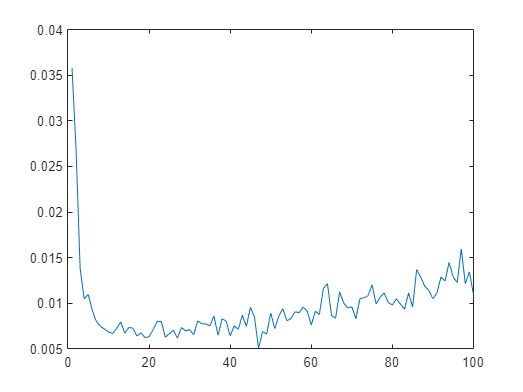

hold off;

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

plot(mse_val0,'-');

disp('training index of best MSE value set is')
disp(I0)
disp('Which has MSE =')
disp(M0)
hold off;


net1 = fitnet(47,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 47
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'poslin';

[net1,tr1] = train(net1,f1(1:4,:),f1(5:6,:));

output_ANN1 = net1(pn)

output_ANN1 =     0.3893    0.3822    0.3437    0.6816    0.7443    0.7771    0.4856    0.5252    0.5779    0.5780    0.6022    0.6394    0.6720    0.7135    0.7992    0.6277    0.6127    0.6302    0.7142    0.7471    0.7641    0.7733    0.7896    0.8689    0.7967    0.8335    0.7916    0.9050    0.9522    0.9618    0.9217    0.9595    0.9162    0.9041    0.9378    0.9565    0.3039    0.3238    0.2838    0.2551    0.2534    0.2080    0.2342    0.2227    0.2327    0.6206    0.6237    0.6021    0.3498    0.3648
    0.1086    0.4468    0.7241   -0.0026    0.3352    0.6296    0.0709    0.3569    0.6503    0.1180    0.4827    0.6557    0.0522    0.4232    0.6997    0.0860    0.3903    0.7474    0.1008    0.5429    0.5712    0.0488    0.4384    0.6291    0.1256    0.3754    0.7440    0.0495    0.5822    0.4944    0.0338    0.4470    0.5464    0.1020    0.3936    0.5866    0.0932    0.4958    0.5891    0.0900    0.4323    0.6420    0.1090    0.4099    0.7702    0.0836    0.5766    0.5392    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =    88.7811   87.8362   82.7310  127.5831  135.8957  140.2569  101.5611  106.8132  113.8088  113.8220  117.0393  121.9723  126.3024  131.8145  143.1852  120.4274  118.4308  120.7504  131.9045  136.2676  138.5254  139.7448  141.9186  152.4444  142.8522  147.7398  142.1745  157.2242  163.4880  164.7695  159.4490  164.4694  158.7181  157.1148  161.5893  164.0633   77.4416   80.0889   74.7751   70.9707   70.7471   64.7168   68.1955   66.6709   67.9925  119.4781  119.8889  117.0292   83.5438   85.5248


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.9148    1.4916    1.9646    0.7252    1.3013    1.8035    0.8505    1.3383    1.8387    0.9309    1.5528    1.8479    0.8187    1.4513    1.9230    0.8762    1.3953    2.0044    0.9015    1.6555    1.7038    0.8128    1.4774    1.8025    0.9439    1.3698    1.9986    0.8140    1.7226    1.5728    0.7873    1.4919    1.6615    0.9035    1.4009    1.7300    0.8885    1.5752    1.7344    0.8830    1.4669    1.8246    0.9155    1.4286    2.0433    0.8722    1.7130    1.6492    0.9050    1.6446


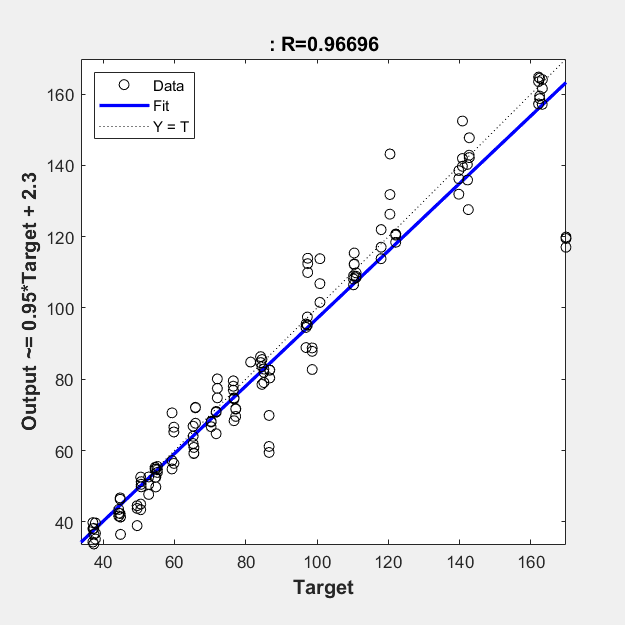

plotregression(t1,ANNIPF)

%plotregression(t2,ANNSEA)
% plotregression(t1n,output_ANN1(1,:));
% plotregression(t2n,output_ANN1(2,:));


pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.1913
    0.5784



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 62.5039

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.7162e+03


maxipf=max(data(:,5))

maxipf = 169.8391

minipf=min(data(:,5))

minipf = 37.1100

maxsea=max(data(:,6))

maxsea = 2.4352e+03

minsea=min(data(:,6))

minsea = 729.5885

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.